syms K tau s t x c

data = readtable("C:\Users\spoka\OneDrive - Olin College of Engineering\Desktop\Olin\0 Semester 4\ESA\Final Project\slower_calibration.csv"); %this path is hardcoded to the one on my computer
left_wheel = data.Var1;
right_wheel = data.Var2;
t = linspace(0,3,141);
%cftool

M(s) = (K/tau)/(s+1/tau)*c/s

$$M(s) = \frac{K\,c}{s\,\tau \,\left(s+\frac{1}{\tau }\right)}$$

mt = ilaplace(M(s))

$$mt = K\,c-K\,c\,{\mathrm{e}}^{-\frac{t}{\tau }}$$

%fmt = matlabFunction(subs(mt,t,x))

mmean = 3;
mmr = movmean(right_wheel,mmean);
clf; hold on;
plot(t,right_wheel,"b-","DisplayName","Raw Wheel Data")
plot(t,mmr,"r--","DisplayName","Move Mean Wheel Data")
Fit1 = fit(t',mmr,@(K,tau,c,x) K*c*(1-exp(-x/tau)))

Fit1 =      General model:
     Fit1(x) = K*c*(1-exp(-x/tau))
     Coefficients (with 95% confidence bounds):
       K =      0.5091  (-5.639e+05, 5.639e+05)
       tau =      0.0958  (0.0928, 0.09881)
       c =       0.805  (-8.917e+05, 8.917e+05)

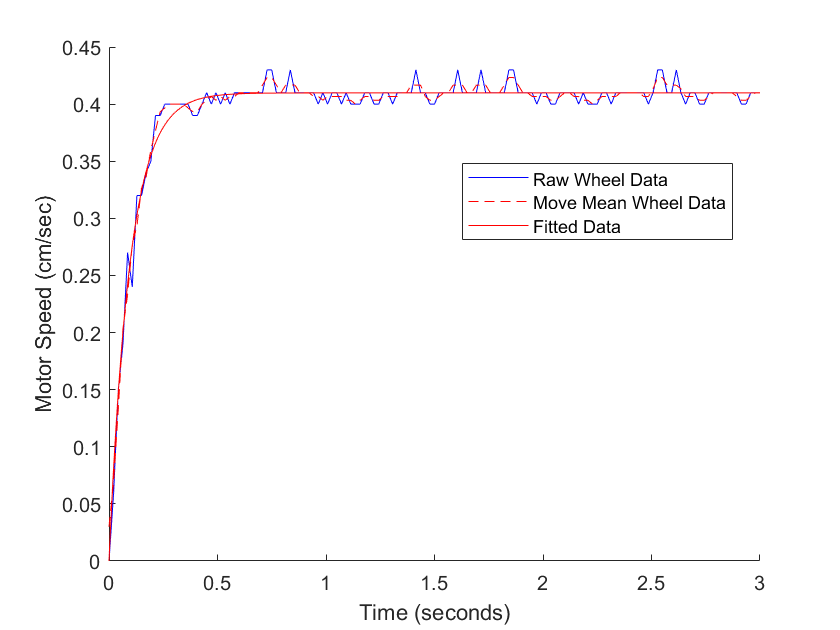

%Fit1 = fit(t',mmr,fmt,'StartPoint', [0, mmr(1)])
plot(Fit1)
xlim([0,3])
legend(["Raw Wheel Data","Move Mean Wheel Data","Fitted Data"],"location","best")
xlabel("Time (seconds)"); ylabel("Motor Speed (cm/sec)")

%K = 0.5091
%tau = 0.0958
%c = 0.805